# **Daisy World**

%% DEFINIZIONE DELLE COSTANTI
clear all

% Costante di Boltzmann
sigma = 5.67E-8;

% Albedo
a_b = 0.25;     % Margherite nere
a_w = 0.75;     % Margherite bianche
a_g = 0.5;      % Suolo

%
q = 20;

% Suolo occupabile
p = 1;

% 
f = 0.003265;

% Radiazione di fondo
S_0 = 1000;

%Areee iniziali occupate
area_b_ini = 0.2;   % Margherite nere
area_w_ini = 0.2;   % Margherite bianche

% Luminosità massima
max_l = 1.55;

% Luminosità minima
min_l = 0.7;

% Argomento del seno della perturbazione periodica
pert_per = (0.4*pi);

% Media per la perturbazione random (uniforme)
pert_rnd = 0.001;

## 1 - Radiazione incidente linearmente crescente

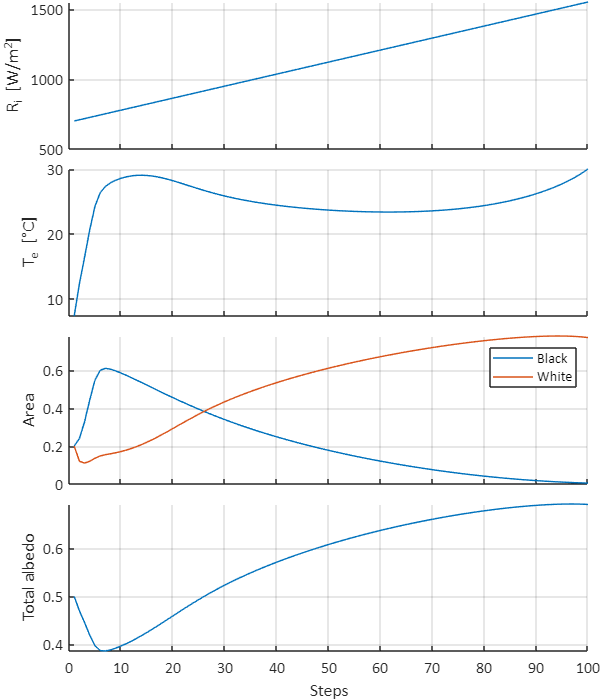

% Costruzione della luminosità
t = linspace(1,100,100);
l = linspace(min_l,max_l,length(t));

% Costruzione tasso di mortlità
mu = ones([1 length(t)])*0.2;      % Mortalità costante

% Simulazione
[T_e, area_b, area_w, area_g, albedo_p] = simulate_world( ...
S_0, l, ... 
a_b, a_w, a_g, ...
area_b_ini, area_w_ini, ...
q, mu, p, f, sigma);

%Plot dei risultati
F1 = figure;
F1.Position = [90 90 600 700];
plot_w = plot_world(S_0, l, T_e, area_b, area_w, albedo_p, t);

## 2 - Radiazione  incidente come funzione spezzata periodica 

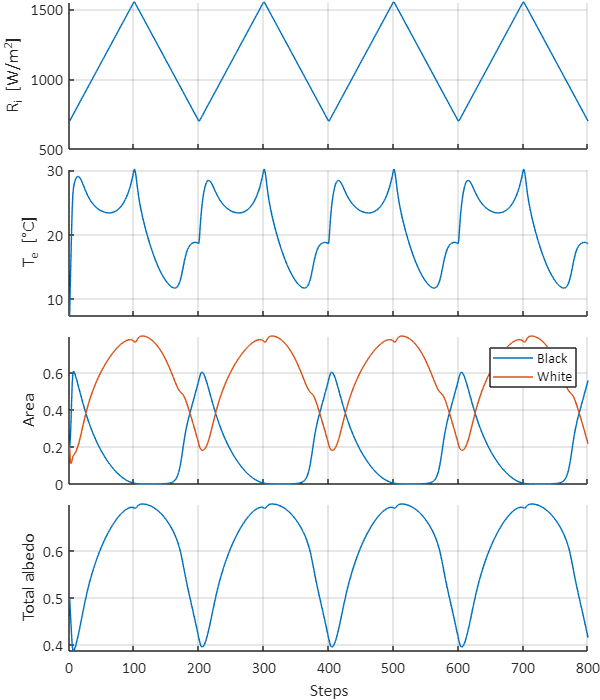

% Costruzione della luminosità
t = linspace(1,800,800);
l = [linspace(min_l,max_l,length(t)/8) linspace(max_l,min_l,length(t)/8) linspace(min_l,max_l,length(t)/8) linspace(max_l,min_l,length(t)/8)...
    linspace(min_l,max_l,length(t)/8) linspace(max_l,min_l,length(t)/8) linspace(min_l,max_l,length(t)/8) linspace(max_l,min_l,length(t)/8)];

% Costruzione tasso di mortlità
mu = ones([1 length(t)])*0.2;      % Mortalità costante

% Simulazione
[T_e_1, area_b_1, area_w_1, area_g_1, albedo_p_1] = simulate_world( ...
S_0, l, ... 
a_b, a_w, a_g, ...
area_b_ini, area_w_ini, ...
q, mu, p, f, sigma);

%Plot dei risultati
F1 = figure;
F1.Position = [90 90 600 700];
plot_w = plot_world(S_0, l, T_e_1, area_b_1, area_w_1, albedo_p_1, t);

## 3 - Radiazione incidente linearmente crescente con disturbo

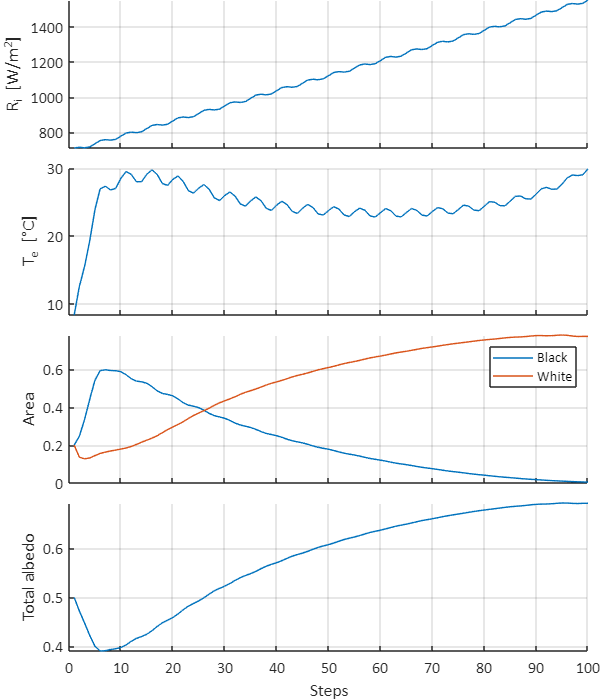

% Costruzione della luminosità linearmente crescente
t = linspace(1,100,100);
l = linspace(min_l,max_l,length(t));

% Costruzione tasso di mortlità
mu = ones([1 length(t)])*0.2;      % Mortalità costante

% Aggiune un po' di rumore deterministico
noise = 0.01*sin(pert_per*t);

% Aggiunge un po' di rumore random (uniforme)
x = random('uniform',0,pert_rnd,[1 length(t)]);

% Componsizione dei rumori col segnale
l = l + noise + x;

% Simulazione dello scenario
[T_e, area_b, area_w, area_g, albedo_p] = simulate_world( ...
S_0, l, ... 
a_b, a_w, a_g, ...
area_b_ini, area_w_ini, ...
q, mu, p, f, sigma);

% Plot dei risultati
F2 = figure;
F2.Position = [90 90 600 700];
plot_w = plot_world(S_0, l, T_e, area_b, area_w, albedo_p, t);

## 4 - Radiazione  incidente come funzione spezzata periodica con disturbo

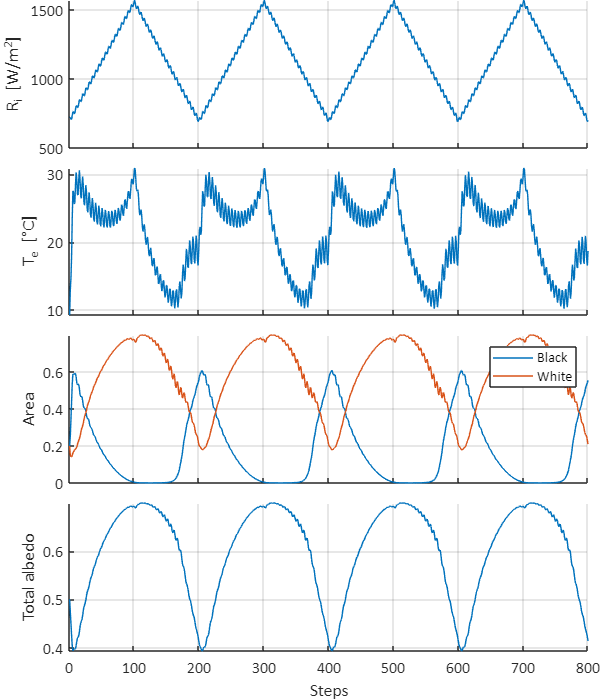

% Costruzione della luminosità
t = linspace(1,800,800);
l = [linspace(min_l,max_l,length(t)/8) linspace(max_l,min_l,length(t)/8) linspace(min_l,max_l,length(t)/8) linspace(max_l,min_l,length(t)/8)...
    linspace(min_l,max_l,length(t)/8) linspace(max_l,min_l,length(t)/8) linspace(min_l,max_l,length(t)/8) linspace(max_l,min_l,length(t)/8)];

% Costruzione tasso di mortlità
mu = ones([1 length(t)])*0.2;      % Mortalità costante

% Aggiune un po' di rumore deterministico
noise = 0.02*sin(pert_per*t);

% Aggiunge un po' di rumore random (uniforme)
x = random('uniform',0,pert_rnd,[1 length(t)]);

% Componsizione dei rumori col segnale
l = l + noise + x;

% Simulazione dello scenario
[T_e, area_b, area_w, area_g, albedo_p] = simulate_world( ...
S_0, l, ... 
a_b, a_w, a_g, ...
area_b_ini, area_w_ini, ...
q, mu, p, f, sigma);

% Plot dei risultati
F1 = figure;
F1.Position = [90 90 600 700];
plot_w = plot_world(S_0, l, T_e, area_b, area_w, albedo_p, t);